## Final Project

Annie and Samuel

Final Project, Project Bank, Question 1

Smart Home Energy Dashboard

Tasks:

- Create or obtain a dataset of hourly (or daily) energy usage (kWh) over 3-6 weeks.

- Clean data (missing values, unit consistency) and compute weekly totals and peak hours.

- Create: (i) time-series plot, (ii) histogram of usage, (iii) weekday vs weekend comparison, (iv) summary dashboard.

- Propose two interventions (behavior or scheduling) and quantify potential impact with simple 'what-if' changes.

Part 1:

The data set to be used for this model was created in Excel. The data lasts for six weeks, and starts on a Monday. All the usage data is in kWh and there are no days missing. 

table = readtable('SmartHomeEngeryData.xlsx'); % importing the data spreadsheet
display(table)

table = 42×2 table
    Days    Energy_Usage1
    ____    _____________

      1          28      
      2          28      
      3          28      
      4          28      
      5          30      
      6          32      
      7          33      
      8          28      
      9          28      
     10          28      
     11          28      
     12          29      
     13          31      
     14          32      
     15          28      
     16          28      


Part 2:

Since the data was created, and everything is already consistent, in this section the weekly totals of every usage is computed along with the peak days of usage. 

T = table2array(table); % converting the table to an array to make it easier to work with
for k = 1:6 % creating a for loop to calculate the average usage values for each week
    mean(T((k*7-6):k*7,2)) % using the mean function to find the average usage values per week
end % end of loop

ans = 29.5714

ans = 29.1429

ans = 29.4286

ans = 29.4286

ans = 29.2857

ans = 24.7143


for k = 1:6 % creating a loop to calculate the maximum usage values for each week
    max(T((k*7-6):k*7,2)) % function for finding the max values, with a return of what the max values are
end % end of loop

ans = 33

ans = 32

ans = 33

ans = 33

ans = 33

ans = 30

Part 3:

Creating histograms, graphs, and comparing the data

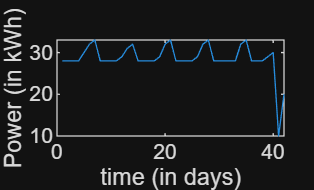

% time-series plot
plot(T(:,1), T(:, 2)); % creating a graph of usage over time. 
xlabel('time (in days)'); % x axis label
ylabel('Power (in kWh)'); % y axis label

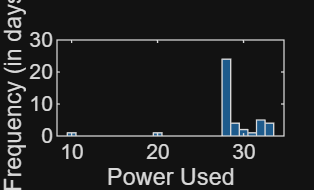


% histogram
histogram(T(:,2)); % creating a histogram of power usage
xlabel('Power Used'); % labeling horizontal axis of the histogram
ylabel('Frequency (in days)'); % labeling the vertical axis of the histogram


% weekday vs weekend
W = T(6,7,12,)

Part 4:

Ways to decrease energy consumption.